## Simulink и маятники

### Модель первая: простейший математический маятник

*Всякий Boston Dynamics начинается с первой модели*

    Сначала нами было смоделировано движение "обычного" маятника - шарика на лёгком нерастяжимом упругом стержне (простейшего математического маятника), с учётом сил трения. Для этого маятника было изучено поведение угла и угловой скорости, а также изменение кинетической, потенциальной и полной энергий.

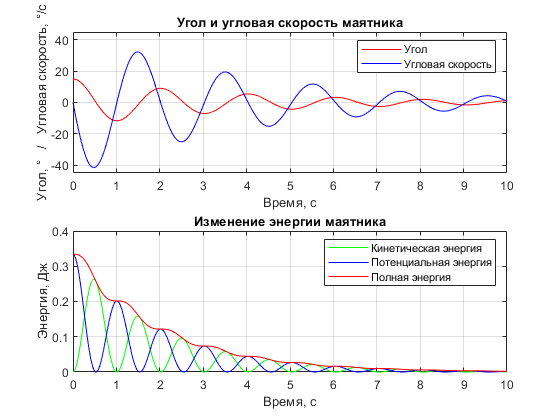

figure('Name','Model 1','NumberTitle','off');

run_1 = sim('pendulum_1');
p_1_theta = run_1.theta;
p_1_dtheta = run_1.dtheta;
p_1_K = run_1.K;
p_1_P = run_1.P;
p_1_Sum = run_1.Sum;

% График углов и угловой скорости
subplot(2, 1, 1);
plot(p_1_theta, 'r');
hold on;
plot(p_1_dtheta, 'b');
grid on;
legend('Угол', 'Угловая скорость');
title('Угол и угловая скорость маятника');
xlabel('Время, с');
ylabel('Угол, °   /   Угловая скорость, °/с');
axis([0 10 -45 45])
hold off;

% График энергий
subplot(2, 1, 2);
plot(p_1_K, 'g');
hold on;
plot(p_1_P, 'b');
hold on;
plot(p_1_Sum, 'r');
grid on;
legend('Кинетическая энергия', 'Потенциальная энергия', 'Полная энергия');
title('Изменение энергии маятника');
xlabel('Время, с');
ylabel('Энергия, Дж');
axis([0 10 0 0.4]);
hold off;

    Как видно на получившихся графиках, со временем и угол, и угловая скорость затухают; кинетическая, потенциальная и полная энергии также обращаются в нуль и уже не меняются. Это происходит из-за влияния на маятник сил трения и свидетельствует о принятии им устойчивого положения равновесия ("вниз"). При этом на втором графике видно, что кинетическая и потенциальная энергии идут в противофазе и максимум потенциальной энергии достигается при нуле кинетической и наоборот. Это согласуется с законом сохранения энергии и лишний раз демонстрирует его.

    Занятно также наблюдать, что полная энергия маятника меняется не равномерно, а плавными "ступеньками". Глядя на второй график, можно заметить, что полная энергия почти не меняется на максимумах потенциальной энергии, а в промежутках между ними как раз резко "падает". Вероятно, это объясняется тем, что в нашей задаче сила трения зависит от скорости, но не от высоты маятника. В максимумах потенциальной энергии величина скорости шарика минимальна и равна нулю - поэтому в этот момент равна нулю и сила трения и полная энергия не убывает. Вблизи этих максимумов потенциальной энергии скорость мала, поэтому получается некое "плато" полной энергии (а не отдельная точка неубывания; на самом деле, конечно, там получается не горизонтальная прямая, а кривая с очень большим радиусом кривизны). Далее при удалении от этих положений скорость маятника начинает возрастать и полная энергия убывает быстрее, наиболее быстро - в максимумах кинетической энергии, где скорость максимальна (а, следовательно, и сила трения и её работа).

### Модель вторая: маятник Капицы

*Интересно, это про гелий?*

    После простейшего математического маятника нами было смоделировано движение маятника Капицы - также маятника на лёгком нерастяжимом упругом стержне, однако теперь его подвес не неподвижен, а может колебаться вдоль вертикальной оси. Интересным свойством такого маятника является то, что у него можно помимо "стандартного" нижнего положения равновесия зафиксировать верхнее положение равновесия (т.е. маятник направлен вертикально вверх), которое также будет устойчивым. Для этого подвес должен колебаться часто и с малой амплитудой.

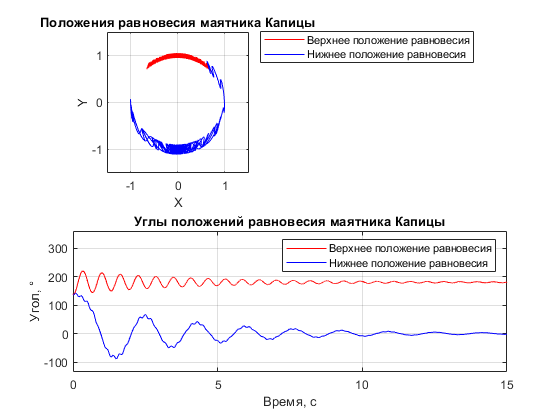

% Начальное отклонение = 135° от нижнего положения

figure('Name','Model 2','NumberTitle','off');

% Верхнее положение равновесия
A = 0.05;
F = 50;
run_2 = sim('pendulum_Kapitsa');
X_up = run_2.X;
Y_up = run_2.Y;
theta_up = run_2.theta;

% Нижнее положение равновесия
A = 0.1;
F = 5;
run_2 = sim('pendulum_Kapitsa');
X_down = run_2.X;
Y_down = run_2.Y;
theta_down = run_2.theta;

% График координат
subplot(2, 1, 1);
plot(X_up, Y_up, 'r', X_down, Y_down, 'b');
grid on;
legend('Верхнее положение равновесия', 'Нижнее положение равновесия', 'Location', 'northeastoutside');
title('Положения равновесия маятника Капицы');
xlabel('X');
ylabel('Y');
axis([-1.5 1.5 -1.5 1.5]);
axis square;
hold off;

% График углов
subplot(2, 1, 2);
plot(theta_up, 'r');
hold on;
plot(theta_down, 'b');
grid on;
legend('Верхнее положение равновесия', 'Нижнее положение равновесия');
title('Углы положений равновесия маятника Капицы');
xlabel('Время, с');
ylabel('Угол, °');
axis([0 15 -135 360]);
hold off;

    На графиках показаны координаты шарика и углы отклонения от вертикали, направленной вниз, для верхнего и нижнего положений равновесия. При этом для обоих положений равновесия одинаков угол начального отклонения маятника (135° от положения вертикально вниз) и различны лишь амплитуда и частота колебаний подвеса.

    Моделирование показывает, что, действительно, у такого маятника существует два устойчивых положения равновесия - нижнее (что весьма предсказуемо) и верхнее.

### Модель третья: обратный маятник

*На стыке теормеха и фантастики*

    Последняя наша модель - модель обратного маятника, т.е. математического маятника, закреплённого на тележке, которая может перемещаться по горизонтальной прямой. При этом движение тележки задаётся так, чтобы удержать маятник в неустойчивом положении равновесия - верхнем.

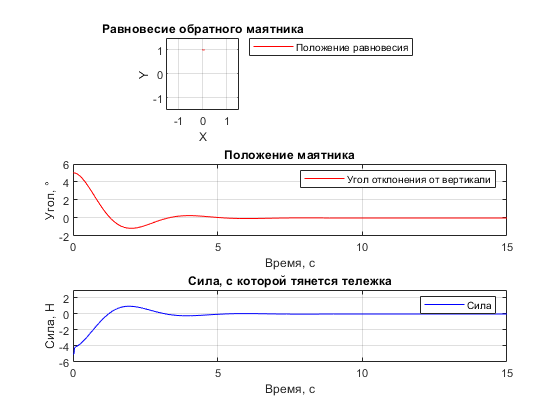

figure('Name','Model 3','NumberTitle','off');

run_3 = sim('pendulum_cart');

X_1 = run_3.X;
Y_1 = run_3.Y;
F_1 = run_3.F;
theta_1 = run_3.theta;

% График координат
subplot(3, 1, 1);
plot(X_1, Y_1, 'r');
grid on;
legend('Положение равновесия', 'Location', 'northeastoutside');
title('Равновесие обратного маятника');
xlabel('X');
ylabel('Y');
axis([-1.5 1.5 -1.5 1.5]);
axis square;

% График углов
subplot(3, 1, 2);
plot(theta_1, 'r');
grid on;
legend('Угол отклонения от вертикали');
title('Положение маятника');
xlabel('Время, с');
ylabel('Угол, °');
axis([0 15 -2 6]);

% График силы
subplot(3, 1, 3);
plot(F_1, 'b');
grid on;
legend('Сила');
title('Сила, с которой тянется тележка');
xlabel('Время, с');
ylabel('Сила, Н');
axis([0 15 -6 3]);

    Из графиков видно, что тележка смогла привести маятник в положение верхнего неустойчивого равновесия. При этом и угол маятника, и сила тележки вышли на нуль, что означает, что положение равновесия действительно достигнуто, и дальнейших действий не требуется.